%% writen by Ebenezer P Gnanamanickam
%% last updated Sep 22

This is a tutorial on the use of trapz for numerical integration. I use the example of integrating a wake and the calculation of drag. The drag per unit depth into the page $D^\prime$ is derived from a control volume analysis (see *Fundamental of Aerodynamics* by John D. Anderson Jr). and is found to be


$$D^\prime = \rho_\infty \int_{-\infty}^{\infty} u_w \left(U_\infty-u_w \right) dy$$


Here $u_w(y)$ is the velocity of the wake and $U_\infty$ is the free stream velocity while $\rho_\infty$ is the free stream density. A demo wake velocity profile has been generated and loaded. Note all units are in SI

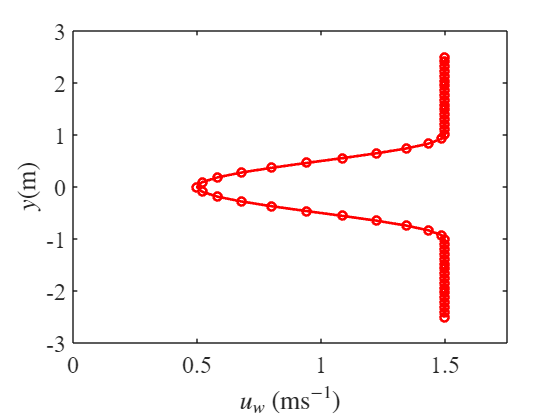

% preamble stuff
clc; clear; close all;
fontSize=18;
set(0,'DefaultTextInterpreter','latex','DefaultAxesLineWidth',1,...
    'DefaultAxesFontSize',fontSize,'DefaultFigureInvertHardCopy',...
    'on','DefaultAxesFontName','Times')

% load demo wake profile (all units in SI)
load demoWakeData.mat

% plot the loaded wake profile
figure
plot(u_w,y,'o-r','LineWidth',2)
ylabel('$y$(m)')
xlabel('$u_w$ (ms$^{-1}$)')
xlim([0 1.75])

Now it is reasonable to assume $U_\infty = u_w$ for all $y$ that lies outside the wake. From the figure it is clear that these are the points above say $\pm 1.1$. I go ahead and calculate now the free stream velocity. From the figure we know that I should get $U_\infty=1.5$ ms$^{-1}$. I also assume that the free stream density is $\rho_\infty=1.2$ kgm$^{-3}$. I have taken the chord of the airfoil to be 1/0.025 m.

U_inf=mean([u_w(y>1.1) u_w(y<-1.1)])

U_inf = 1.5000

rho_inf=1.2;
c=6/.025; %chord length stuff

% drag
D=rho_inf*trapz(y,u_w.*(U_inf-u_w))

D = 0.9001

Cd=D/(0.5*rho_inf*U_inf^2*c)

Cd = 0.0028